clc; clear; clear all; close all;

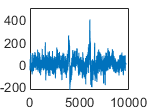

data = edfread("S001R01.edf");
d=data.Fc5_;

d1=zeros(size(d,1)*160,1);

ii=0;
for i=1:size(d,1)
    d1((ii+1):i*160)=d{i};
    ii=i*160;
end
figure
plot(d1);

## 1. İşlem: x = d1 işlemi

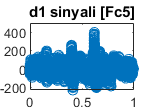

x = d1';
Fs = 9759;  
t = (0:1/Fs:1);

figure;
subplot(1,1,1);  
stem(t, x);
title('d1 sinyali [Fc5]'); figure; Fc5 = imshow ("Fc_5.png");

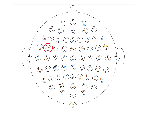

xlabel('Zaman (s)');
ylabel('Genlik');

## 2. İşlem: Örnekleme

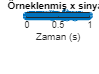

Fs_s = 19520;
Fn = Fs_s / 2; 

n = 0:1/Fs_s:1; 
x_s = x(round(n*Fs)+1);  

figure;
subplot(2,1,1);
stem(n, x_s); 
title('Örneklenmiş x sinyali');
xlabel('Zaman (s)');
ylabel('Genlik');

## 3. İşlem: x sinyalinin zamana göre tersi

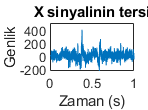

x_reverse = x(length(x):-1:1);

subplot(1,1,1);
plot(t, x_reverse);
title('X sinyalinin tersi');
xlabel('Zaman (s)');
ylabel('Genlik');

## 4. İşlem: x sinyalini zamanda 0.5 sn kaydırma

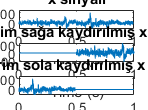

t_shift = 0.5; 
n_shift = round(t_shift*Fs);

x_shift = [zeros(1, n_shift), x(1:end-n_shift)];
x_shift_left=[x(n_shift+1:end), zeros(1,n_shift)];

subplot(3,1,1);
plot(t, x);
title('x sinyali');
xlabel('Time (s)');
ylabel('Amplitude');
subplot(3,1,2);
plot(t, x_shift);
title(sprintf('%.1f birim sağa kaydırılmış x sinyali', t_shift));
xlabel('Time (s)');
ylabel('Amplitude');
subplot(3,1,3);
plot(t, x_shift_left);
title(sprintf('%.1f birim sola kaydırılmış x sinyali', t_shift));
xlabel('Time (s)');
ylabel('Amplitude');

## 5. İşlem: Downsampling (Alt örnekleme)

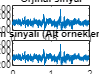

downsampleFactor = 3;
N = length(x_s);t_1 = linspace(0,50,N);
M = floor(N/downsampleFactor);
x_rsd = zeros(1, M);

for i = 1:M
    x_rsd(i) = x_s((i-1)*downsampleFactor+1);
end

n_downsampled = 0:1/(Fs/downsampleFactor):(M-1)/(Fs/downsampleFactor);
figure;
subplot(2,1,1);
plot(n, x_s);
title('Orjinal sinyal');
xlabel('Zaman (s)');
ylabel('Genlik');
subplot(2,1,2);
plot(n_downsampled, x_rsd);
title(sprintf('Alt örneklem sinyali (Alt örneklem faktörü: %.f)',downsampleFactor));
xlabel('Zaman (s)');
ylabel('Genlik');

## 6. İşlem: Upsample (Üst örnekleme)

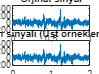

upsampleFactor=10;
N = length(x_s);
M = N * upsampleFactor;
x_rsu = zeros(1, M);

for i = 1:N
    x_rsu((i-1)*upsampleFactor+1) = x_s(i);
end

n_upsampled = 0:1/(Fs*upsampleFactor):(M-1)/(Fs*upsampleFactor);

figure;
subplot(2,1,1);
plot(n, x_s);
title('Orjinal sinyal');
xlabel('Zaman (s)');
ylabel('Genlik');
subplot(2,1,2);
plot(n_upsampled, x_rsu);
title(sprintf('Üst örneklem sinyali (Üst örneklem faktörü: %.f)',upsampleFactor));
xlabel('Zaman (s)');

ylabel('Genlik');

## SİNC fonsiyonsu

% t = -10:0.1:10;
% y = sinc(t);
% stem(t, y);
% xlabel('Zaman');
% ylabel('Sinc Fonksiyonu');
% title('Sinc Fonksiyonu Grafiği');

## 7. İşlem: Konvolsüyon (Convolution)

% z = zeros(size(n));
% 
% for k = 1:length(n)
%     for m = 1:k
%         z(k) = z(k) + x(m)*y(k-m+1);
%     end
%     stem(z);pause(1);
% end
% 
% j=0:1:20;
% subplot(3,1,1)
% stem(j,x)
% title('Basamak fonksiyonu (Step Function)')
% xlabel('n')
% ylabel('x(n)')
% xlim([min(j),max(j)]);
% subplot(3,1,2)
% stem(j,y)
% title('Azalan üstel Sinyal')
% xlabel('n')
% ylabel('y(n)')
% xlim([min(j),max(j)]);
% subplot(3,1,3)
% stem(j,z)
% title('Konvolüsyon sonucu')
% xlabel('n')
% ylabel('z(n)')
% xlim([min(j),max(j)]);

## 8. İşlem: Konvolüsyon ile filtreleme -  (sinc fonk.)

fc = 15;
fs = 9759;

t_filter = (-9759:9759)/fs;
b = (2*fc/fs)*sinc(2*fc*t_filter); plot(b);
x=d1;

y = conv(x, b);
t=linspace(0,10,length(x));

figure;
subplot(2,1,1);
plot(t, x);
title('Orjinal Sinyal');
subplot(2,1,2);
plot(t, y(9760:end-9759));
title(sprintf('Filtrelenmiş Sinyal - Köşe Frekansı fc = %.f', fc));

% Ana sinyalimizin ve sinc fonksiyonumuzun FFT işlemleri: 

x_f=fft(x); % x bizim orjinal sinyalimiz.
b_f=fft(b); % b bizim sinc fonksiyonumuz.

subplot(2,1,1);
plot(fftshift(imag(sqrt(x_f).^2+real(x_f).^2)));

subplot(2,1,2);
plot(fftshift(imag(sqrt(b_f).^2+real(b_f).^2)));

## x[n] Sinyalinin Sinc Fonksiyonu ile Konvolüsyonu [2. YOL]

% t = -10:0.1:10; 
% sinc_func = sinc(t); 
% plot (sinc_func);
% 
% y = conv(x, sinc_func, 'same');
% stem(y);
% xlabel('n'); 
% ylabel('Konvolüsyon Sonucu'); 
% title('x[n] Sinyalinin Sinc Fonksiyonu ile Konvolüsyonu');

## 9. İşlem: x[n] Sinyalinin Kare Dalga Fonksiyonu ile Konvolüsyonu

t = 0:1/Fs_s:1; 
square_wave = square(2*pi*5*t); 

y_square = conv(x_s, square_wave, 'same');

figure;
subplot(2,1,1);
stem(n, x_s); 
title('Örneklenmiş x sinyali');
xlabel('Zaman (s)');
ylabel('Genlik');

subplot(2,1,2);
stem(n, y_square);
title('Konvolüsyon Sonucu (Kare Dalga)');
xlabel('Zaman (s)');
ylabel('Genlik');

## 10. İşlem: x[n] Sinyalinin Üçgen Dalga Fonksiyonu ile Konvolüsyonu

t = 0:1/Fs_s:1; 
triangle_wave = sawtooth(2*pi*5*t, 0.5);

y_triangle = conv(x_s, triangle_wave, 'same');

maks_deger = max(y_triangle)
min_deger = min(y_triangle)
genlik = (maks_deger - min_deger) / 2

figure;
subplot(2,1,1);
stem(n, x_s); 
title('Örneklenmiş x sinyali');
xlabel('Zaman (s)');
ylabel('Genlik');

subplot(2,1,2);
stem(n, y_triangle);
title('Konvolüsyon Sonucu (Üçgen Dalga)');
xlabel('Zaman (s)');
ylabel('Genlik');

## 11. İşlem: x[n] Sinyalinin Gauss Yayılımı ile Konvolüsyonu

t = -1:1/Fs_s:1;
stsp = 0.01;
gaussian = exp(-t.^2/(2*(stsp)^2));

y_gaussian = conv(x_s, gaussian, 'same');

figure;
subplot(2,1,1);
stem(n, x_s); 
title('Örneklenmiş x sinyali');
xlabel('Zaman (s)');
ylabel('Genlik');

subplot(2,1,2);
stem(n, y_gaussian);
title(sprintf('Konvolüsyon Sonucu (Gauss Yayılımı) - Standat Sapma: %.3f', stsp ));
xlabel('Zaman (s)');
ylabel('Genlik');

## 12. İşlem: x[n] Sinyalinin Dirac Delta ile Konvolüsyonu

dirac_delta = zeros(size(n));
dirac_delta(round(numel(n)/2)) = 1;

y_dirac = conv(x_s, dirac_delta, 'same');

figure;
subplot(2,1,1);
stem(n, x_s); 
title('Örneklenmiş x sinyali');
xlabel('Zaman (s)');
ylabel('Genlik');

subplot(2,1,2);
stem(n, y_dirac);
title('Konvolüsyon Sonucu');

## 13. İşlem: x[n] Sinyalinin Cosinus Dalga ile Konvolüsyonu

t = 0:1/Fs_s:1; 
cos_wave = cos(2*pi*10*t); 

y_cos = conv(x_s, cos_wave, 'same');

figure;
subplot(2,1,1);
stem(n, x_s); 
title('Örneklenmiş x sinyali');
xlabel('Zaman (s)');
ylabel('Genlik');

subplot(2,1,2);
stem(n, y_cos);
title('Konvolüsyon Sonucu (Cosinus Dalga)');
xlabel('Zaman (s)');
ylabel('Genlik');

## 14. İşlem: x[n] Sinyalinin Sinüs Dalga ile Konvolüsyonu

t = 0:1/Fs_s:1;
sin_wave = sin(2*pi*5*t);

y_sin = conv(x_s, sin_wave, 'same');

figure;
subplot(2,1,1);
stem(n, x_s); 
title('Örneklenmiş x sinyali');
xlabel('Zaman (s)');
ylabel('Genlik');

subplot(2,1,2);
stem(n, y_sin);
title('Konvolüsyon Sonucu (Sinüs Dalga)');
xlabel('Zaman (s)');
ylabel('Genlik');


## 15. İşlem: DFT ve IDFT İşlemleri

x = d1;

X = fft(x);
magnitude = abs(X);
phase = angle(X);

N = length(x);
fs = 9759;
f = (0:N-1)*(fs/N);

figure;
subplot(2,1,1);
stem(f, magnitude);
title('DFT - Büyüklük (Magnitude)');
xlabel('Frekans (Hz)');
ylabel('Genlik');

subplot(2,1,2);
stem(f, phase);
title('DFT - Faz (Phase)');
xlabel('Frekans (Hz)');
ylabel('Faz');

%% IDFT 

x_reconstructed = ifft(X);

N = length(x_reconstructed);
fs = 9759;
t = (0:N-1) / fs;

figure;
plot(t, real(x_reconstructed));
title('Ters Fourier Dönüşümü');
xlabel('Zaman (s)');
ylabel('Genlik');

## 16. İşlem: Alçak Geçiren Filtre (LPF)

fc = 1000; 
fs = 9759; 

N = 51; 
h = fir1(N-1, fc/(fs/2));

y_lpf = conv(x, h, 'same');

figure;
subplot(2,1,1);
plot(t, x);
title('Orijinal Sinyal');
xlabel('Zaman (s)');
ylabel('Genlik');

subplot(2,1,2);
plot(t, y_lpf);
title(sprintf('LPF Uygulanmış Sinyal - Kesme Frekansı (fs)= %.f', fc));
xlabel('Zaman (s)');
ylabel('Genlik');

## 17. İşlem: Yüksek Geçiren Filtre (HPF)

fc = 500; 
fs = 9759; 

N = 51; 
h = fir1(N-1, fc/(fs/2), 'high');

y_hpf = conv(x, h, 'same');

figure;
subplot(2,1,1);
plot(t, x);
title('Orijinal Sinyal');
xlabel('Zaman (s)');
ylabel('Genlik');

subplot(2,1,2);
plot(t, y_hpf);
title(sprintf('HPF Uygulanmış Sinyal - Kesme Frekansı (fs)= %.f', fc));
xlabel('Zaman (s)');
ylabel('Genlik');

## 18. İşlem: Bant Geçiren Filtre (BPF)

fc1 = 1000; %alt
fc2 = 2500 %üst
fs = 9759;
N = 51; 
h = fir1(N-1, [fc1 fc2]/(fs/2), 'bandpass');

y_bpf = conv(x, h, 'same');

figure;
subplot(2,1,1);
plot(t, x);
title('Orijinal Sinyal');
xlabel('Zaman (s)');
ylabel('Genlik');

subplot(2,1,2);
plot(t, y_bpf);
title(sprintf('BPF Uygulanmış Sinyal - ALt Kesme Frekansı: %.f, Üst Kesme Frekansı: %.f', fc1,fc2));
xlabel('Zaman (s)');
ylabel('Genlik');

## 19. İşlem: Bant Duran Filtre (BSF)

f1 = 1000; %alt
f2 = 2500;%üst
fs = 9759; 
N = 51; 
h = fir1(N-1, [f1/(fs/2), f2/(fs/2)], 'stop');

y_bsf = conv(x, h, 'same');

figure;
subplot(2,1,1);
plot(t, x);
title('Orijinal Sinyal');
xlabel('Zaman (s)');
ylabel('Genlik');

subplot(2,1,2);
plot(t, y_bsf);
title(sprintf('BSF Uygulanmış Sinyal - ALt Kesme Frekansı: %.f, Üst Kesme Frekansı: %.f', f1,f2));
xlabel('Zaman (s)');
ylabel('Genlik');

## 20. İşlem: DFT

N = 1000; dT = 1/N; t = (0:N-1)*dT; 
A1=5;A2=6;
f1 = 50; f2 = 20;  
xn = A1*sin(2*pi*(f1)*t)+A2*cos(2*pi*(f2)*t);
Ft = (0:1/N:1/2)/dT; % Fourier Frekansý
n  = 0:N-1;       m  =  n(1:floor(N/2)+1);  
tn = n;           fm = m/N;          
wm = 2*pi*fm;  

Cx = zeros(floor(size(xn)/2)+1);  
for m = 1:length(wm)  
    Cx(m) = sum( xn(:) .* exp(-1i*wm(m)*tn(:)) ) * dT;  
end  
rc = real(Cx);    ic = imag(Cx);


subplot(211), plot(t,xn), xlabel('zaman, saniye'), ylabel('x, m')  
title('Complex Fourier transform örneði')
subplot(212), plot(Ft,rc,Ft,ic,[f1 f2],[0 0],'ro');xlim([0,100]);   
xlabel('frequency, cycle/sec'), ylabel('Cx, m sec');

## a değer aralığının tanımlanması

% a_range = linspace(0, 0.5, 100);
% 
% for i = 1:length(a_range)
%     % Define the signal a^nu[n] for the current a value
%     a = a_range(i);
%     n = 0:19;
%     x = a.^n;
% 
%     % Compute the DFT of the signal
%     X = fft(x);
% 
%     % Compute the frequency axis
%     %freq=linspace(-2*pi,2*pi,length(x));
%     freq = 0:1/length(x):1-1/length(x);
% 
%     % Plot the magnitude and phase of the DFT
%     subplot(2,1,1);
%     plot(freq, abs(X));
%     xlabel('Frequency');
%     ylabel('Magnitude');
%     title(sprintf('Magnitude of DFT (a = %0.2f)', a));
% 
%     subplot(2,1,2);
%     plot(freq, angle(X));
%     xlabel('Frequency');
%     ylabel('Phase');
%     title(sprintf('Phase of DFT (a = %0.2f)', a));
% 
%     b=1./(1-a*exp(-1i*freq));plot(freq,abs(b));
%     % Pause to display each plot before moving on to the next a value
%     pause(0.1);
% end
% 
% b=1./(1-a*exp(-1i*freq));plot(freq,b);

## 12. İşlem: Inverse DFT

X=zeros(101,1);
ohm=-5:0.1:5;
X(39,1)=1.5*pi; X(63,1)=1.5*pi;
plot(ohm,X);

N = length(X);

## 13. İşlem: Filtreleme


N = 10000; dT = 1/N; t = (0:N-1)*dT; 
A1=5;A2=6;
f1 = 50; f2 = 20; f3=75;f4=150;f5=250; 
xn = A1*sin(2*pi*(f1)*t)+A2*cos(2*pi*(f2)*t)+0.4*cos(2*pi*(f3)*t)+0.8*cos(2*pi*(f4)*t)+1.1*cos(2*pi*(f5)*t);
Ft = (-1/2:1/N:((1/2)-1/N))/dT; % Fourier Frekansý
plot(t,xn);
S = fft(xn);
P = abs(S).^2; %Power Spektrum

plot(Ft,fftshift(abs(S)))
ylim([0,5*10^5]);xlim([-700,700])


## İdeal filtre 

fc = 500; % Cutoff frequency
%%n = 4; % Filter order

% Generate the ideal filter
H_ideal = zeros(size(S));
H_ideal(1:fc+1) = 1;
H_ideal(end-fc+1:end) = 1;

%H_ideal=1-H_ideal;
plotyy(Ft,fftshift(abs(H_ideal)),Ft,fftshift(abs(S))); 
Y=S.*H_ideal;
plot(Ft,abs(fftshift(Y)));
s_ideal = abs(ifft(Y)); plot(t,s_ideal);

## 14. İşlem: **Gauss Fitre**

fc = 25; 
%sigma = 2*pi*fc;
sigma=4.5;
N = length(xn); 
n = -(N-1)/2:(N-1)/2; 
g = exp(-n.^2/(2*sigma^2)); 
g = g/sum(g);
H_gauss = fftshift(fft(g, N));


plotyy(Ft,abs(H_gauss),Ft,fftshift(abs(S))); 

s_gauss = real(ifft(S.*H_gauss)); plot(s_gauss); plot(Ft,abs(fftshift(fft(s_gauss))));

## 15. İşlem: ButterWorth Filtre


fc = 20; 
n = 4; 

Wn = fc/(fs/2);
[B, A] = butter(n, Wn, 'low');


H_butter = freqz(B, A, length(P), 'whole')';
plotyy(Ft,fftshift(abs(H_butter)),Ft,fftshift(abs(S))); 


s_butter = real(ifft(S.*H_butter));  plot(s_butter);


## 16. İşlem: Ideal Band Pass

fs=N;
f_low = 150; 
f_high = 155; 

N = length(P); 
H_ideal = zeros(N,1); 
k_low = round(f_low/(fs/N)); 
k_high = round(f_high/(fs/N)); 
H_ideal(k_low:k_high) = 1; 
H_ideal(N-k_high:N-k_low) = 1;
H_ideal=(1-H_ideal);
plotyy(Ft,fftshift(abs(H_ideal)),Ft,fftshift(abs(S))); 
Y=S.*H_ideal'; %% Band stop filter

s_ideal = real((ifft(Y))); plot(s_ideal);

subplot(2,1,1);plot(xn);title('filtrelemeden önce')
subplot(2,1,2);plot(s_ideal);title('20-80 Hz bastırılmış aralık')



## 17. İşlem: Gauss Band Pass

f_low = 140; 
f_high = 180;
sigma = 10; 

N = length(P); 
f = (0:N-1)*(fs/N); 
H_gauss = exp(-(f-f_low).^2/(2*sigma^2)) .* (1 - exp(-(f-f_high).^2/(2*sigma^2)));


plotyy(Ft,fftshift(H_gauss),Ft,fftshift(abs(S))); 

s_gauss = real(ifft(S.*H_gauss)); plot(s_gauss);

## 18. İşlem: ButterWorth Band Pass

f_low = 20; 
f_high = 80; 
N_order = 6; 


N = length(P); 
f = (0:N-1)*(fs/N); 
Wn = [f_low f_high]/(fs/2); 
[B, A] = butter(N_order, Wn, 'bandpass'); 


H_butter = freqz(B, A, f, fs);

plotyy(Ft,fftshift(abs(H_butter)),Ft,fftshift(abs(S))); 

## 19. İşlem: Notch Filter


f_notch = 100; 
Q = 10; 

% ideal notch filter
N = length(P); 
f = (0:N-1)*(fs/N); 
H_notch_ideal = ones(1,N);
idx = find(abs(f-f_notch) < Q);
H_notch_ideal(idx) = 0;

plotyy(Ft,fftshift(abs(H_notch_ideal)),Ft,fftshift(abs(S))); 

%  Gaussian notch filter
sigma = f_notch / Q; 
H_notch_gauss = exp(-(f-f_notch).^2 / (2*sigma^2));

plotyy(Ft,fftshift(abs(H_notch_gauss)),Ft,fftshift(abs(S))); 

% Butterworth notch  filter
f_notch = 100; % 
Q = 10; %
fc1 = (f_notch - f_notch/Q) / (fs/2); % Lower cutoff frequency 
fc2 = (f_notch + f_notch/Q) / (fs/2); % Upper cutoff frequency 


[n, Wn] = buttord([fc1, fc2], [fc1/Q, fc2*Q], 1, 40);
[B, A] = butter(n, Wn, 'stop', 's'); 
H_notch_butter = freqs(B, A, linspace(0, 2*pi*fs, length(P)));

plotyy(Ft,fftshift(abs(H_notch_butter)),Ft,fftshift(abs(S))); 


s_notch_ideal = real(ifft(S.*H_notch_ideal));
s_notch_gauss = real(ifft(S.*H_notch_gauss));
s_notch_butter = real(ifft(S.*H_notch_butter));